%% ---- Post-process QP time from simOut(i).t_qp ----
nCase = numel(simOut);

mean_ms = nan(nCase,1);
med_ms  = nan(nCase,1);
p95_ms  = nan(nCase,1);
nSteps  = nan(nCase,1);

all_ms = [];

for i = 1:nCase
    tq = simOut(i).t_qp;

    if isa(tq,'timeseries')
        tvec = tq.Time(:);
        dvec = tq.Data(:);
    elseif isstruct(tq) && isfield(tq,'time') && isfield(tq,'signals')
        tvec = tq.time(:);
        dvec = tq.signals.values(:);
    else
        error('t_qp must be timeseries or struct-with-time to remove earliest timestamp.');
    end
    
    % remove invalids first (optional but recommended)
    valid = isfinite(tvec) & isfinite(dvec) & ~isnan(dvec) & dvec >= 0;
    tvec = tvec(valid);
    dvec = dvec(valid);
    
    % delete the sample with the earliest timestamp
    [~, idxMin] = min(tvec);
    tvec(idxMin) = [];
    dvec(idxMin) = [];
    
    % now dvec is your per-step time in seconds (startup removed)
    tms = 1000*dvec;
    
    % stats
    mean_ms(i) = mean(tms);
    med_ms(i)  = median(tms);
    p95_ms(i)  = prctile(tms,95);
    nSteps(i)  = numel(tms);
end

Tqp = table((1:nCase).', nSteps, mean_ms, med_ms, p95_ms, ...
    'VariableNames', {'Case','Nsteps','Mean_ms','Median_ms','P95_ms'});
disp(Tqp);

    Case    Nsteps    Mean_ms    Median_ms    P95_ms
    ____    ______    _______    _________    ______

     1       500      8.0936      7.3746       13.94
     2       500      8.0981      7.2176      14.148
     3       500      10.007      8.8814      16.564
     4       500      9.8716       9.143      14.968




fprintf('Overall pooled: mean %.3f ms, median %.3f ms, p95 %.3f ms', ...
    mean(all_ms), median(all_ms), prctile(all_ms,95));

Overall pooled: mean NaN ms, median NaN ms, p95 NaN ms

%% Figure: Working set and RCIS, same rays, clipped fill, one direction line

% Working set: Px ∩ { [0 1] x <= 30 }
Hw = Polyhedron('A',[0 1],'b',30);
Xw = Px & Hw;          % Working set X^d
% Xf is already in the workspace: RCIS

%% ==== 1) Use two points to define the clipping line (only for clipping the filled region) ====
p1 = [39.5365, 21.9647];
p2 = [64.0793+7, 30.0000];   % Slightly extended to the right for a milder slope

m = (p2(2) - p1(2)) / (p2(1) - p1(1));   % Slope
c = p1(2) - m * p1(1) - 5;               % Shift downward by 5 (tunable)

% Half-space: x2 >= m x1 + c  <=>  m x1 - x2 <= -c
Hclip = Polyhedron('A',[m -1], 'b', -c);

% Clipped sets (used only for fill/contour; bounded)
Xw_clip = Xw & Hclip;
Xf_clip = Xf & Hclip;

Vw = Xw_clip.V;
Vf = Xf_clip.V;

GrayColor = 'r';
BlueColor = 'b';

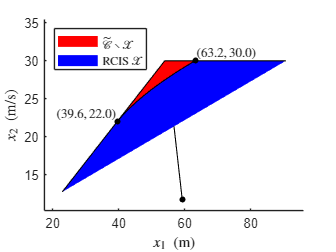

%% ==== 2) Figure: plot working set first, then RCIS ====

figure;
font_size        = 10;
two_column_width = 7;
set(gcf,'Units','inches', ...
    'Position',[1,1,two_column_width/2,two_column_width/2*0.75]);

ax = gca; hold(ax,'on');

tol_line   = 1e-3;  % Distance threshold to classify vertices as "on the clipping line"
edge_width = 0.8;   % Common edge width for both sets

% 2.1 Working set: light fill + black edges (skip the clipped edge)
if ~isempty(Vw)
    Kw = convhull(Vw(:,1), Vw(:,2));
    nW = numel(Kw);

    % Filled region
    hXw = fill(Vw(Kw,1), Vw(Kw,2), GrayColor, 'EdgeColor','none');

    % Draw black edges manually
    for t = 1:nW
        i1 = Kw(t);
        i2 = Kw(mod(t,nW)+1);
        pA = Vw(i1,:);
        pB = Vw(i2,:);

        dA = abs(pA(2) - (m*pA(1) + c));
        dB = abs(pB(2) - (m*pB(1) + c));

        % Skip the edge on the clipping line
        if dA > tol_line || dB > tol_line
            plot([pA(1) pB(1)], [pA(2) pB(2)], 'k-', 'LineWidth', edge_width);
        end
    end
else
    hXw = [];
end

% 2.2 RCIS: light fill + black edges (also skip the clipped edge)
if ~isempty(Vf)
    Kf = convhull(Vf(:,1), Vf(:,2));
    nF = numel(Kf);

    % Filled region
    hXf = fill(Vf(Kf,1), Vf(Kf,2), BlueColor, 'EdgeColor','none');

    % Draw black edges manually
    for t = 1:nF
        i1 = Kf(t);
        i2 = Kf(mod(t,nF)+1);
        pA = Vf(i1,:);
        pB = Vf(i2,:);

        dA = abs(pA(2) - (m*pA(1) + c));
        dB = abs(pB(2) - (m*pB(1) + c));

        % Skip the edge on the clipping line
        if dA > tol_line || dB > tol_line
            plot([pA(1) pB(1)], [pA(2) pB(2)], 'k-', 'LineWidth', edge_width);
        end
    end
else
    hXf = [];
end

%% ==== 3) Single "unbounded direction" ray: start at center of clipped boundary ====

if ~isempty(Xf.R) && ~isempty(Vf)
    R = Xf.R;   % Ray directions

    % 3.1 Normalize all ray directions
    dirs = zeros(size(R));
    for i = 1:size(R,1)
        if norm(R(i,:)) > 0
            dirs(i,:) = R(i,:)/norm(R(i,:));
        end
    end

    % 3.2 Aggregate direction: sum unit directions and renormalize
    dir_mid = sum(dirs,1);
    if norm(dir_mid) < 1e-8
        dir_mid = dirs(1,:);
    end
    dir_mid = dir_mid / norm(dir_mid);

    % Prefer a "downward" pointing ray; flip if pointing upward
    if dir_mid(2) > 0
        dir_mid = -dir_mid;
    end

    % 3.3 Find the segment of Xf_clip on the clipping line, and take its midpoint
    Vf_clip = Xf_clip.V;
    dist_on = abs(Vf_clip(:,2) - (m*Vf_clip(:,1) + c));
    idx_on  = find(dist_on <= 1e-2);      % Slightly relaxed tolerance

    if ~isempty(idx_on)
        % Projection interval [xmin, xmax] of the intersection segment
        x_on = Vf_clip(idx_on,1);
        x_c  = (min(x_on) + max(x_on))/2; % Midpoint in x
        y_c  = m*x_c + c;                 % On the clipping line
        p_on = [x_c, y_c];                % Ray starting point
    else
        % Fallback: use centroid of the polygon + small step in dir_mid
        Kfc  = convhull(Vf_clip(:,1), Vf_clip(:,2));
        poly = Vf_clip(Kfc,:);
        v_in = mean(poly,1);
        Ltmp = 1;                         % Small step length
        p_on = v_in + Ltmp*dir_mid;
    end

    % 3.4 Ray endpoint: from p_on along dir_mid with length L
    L  = 10;                              % Ray length (tunable)
    p2 = p_on + L*dir_mid;

    % 3.5 Plot ray: from boundary center p_on to p2, with solid endpoint marker
    plot([p_on(1) p2(1)], [p_on(2) p2(2)], 'k-', 'LineWidth', 0.8);
    plot(p2(1), p2(2), 'ko', 'MarkerSize', 4, 'MarkerFaceColor','k');
end

%% ==== 4) Axes & legend ====

Vall = [Vw; Vf];
if ~isempty(Vall)
    x1_min = min(Vall(:,1)) - 5.5;
    x1_max = max(Vall(:,1)) + 5.5;
    x2_min = min(Vall(:,2)) - 2.5;
    x2_max = max(Vall(:,2)) + 5.5;
    xlim([x1_min x1_max]);
    ylim([x2_min x2_max]);
end

ylabel('$x_2\ \mathrm{(m/s)}$','Interpreter','latex','FontSize',font_size);
xlabel('$x_1\ \mathrm{(m)}$','Interpreter','latex','FontSize',font_size);
set(ax,'FontSize',font_size);
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;
grid(ax,'off');

%% Mark leftmost and rightmost RCIS vertices (no units, 1 decimal place)
Vx = Xf.V;                       % All RCIS vertices

[~, idx_left]  = min(Vx(:,1));   % Vertex with smallest x1
[~, idx_right] = max(Vx(:,1));   % Vertex with largest x1

pL = Vx(idx_left ,:);
pR = Vx(idx_right,:);

% Black markers
plot(pL(1), pL(2), 'ko', 'MarkerSize',4, 'MarkerFaceColor','k');
plot(pR(1), pR(2), 'ko', 'MarkerSize',4, 'MarkerFaceColor','k');

% Leftmost point: label slightly to upper left
text(pL(1)-19, pL(2)+1, sprintf('$(%.1f,%.1f)$', pL(1), pL(2)), ...
     'Interpreter','latex', 'FontSize', font_size);

% Rightmost point: label slightly to upper left (avoid touching boundary)
text(pR(1), pR(2)+1, sprintf('$(%.1f,%.1f)$', pR(1), pR(2)), ...
     'Interpreter','latex', 'FontSize', font_size);

% Legend
legs   = {};
h_legs = [];
if ~isempty(hXw)
    h_legs(end+1,1) = hXw;
    legs{end+1}     = '$\tilde{\mathcal C}\setminus\mathcal X $ ';
end
if ~isempty(hXf)
    h_legs(end+1,1) = hXf;
    legs{end+1}     = 'RCIS $\mathcal X$';
end
if ~isempty(h_legs)
    legend(h_legs, legs, 'Interpreter','latex', 'Location','northwest');
end

set(gcf,'Units','inches', ...
    'Position',[1,1,two_column_width/2,two_column_width/2*0.75]);

exportgraphics(gcf,'Figures/ACC1.eps','ContentType','vector');

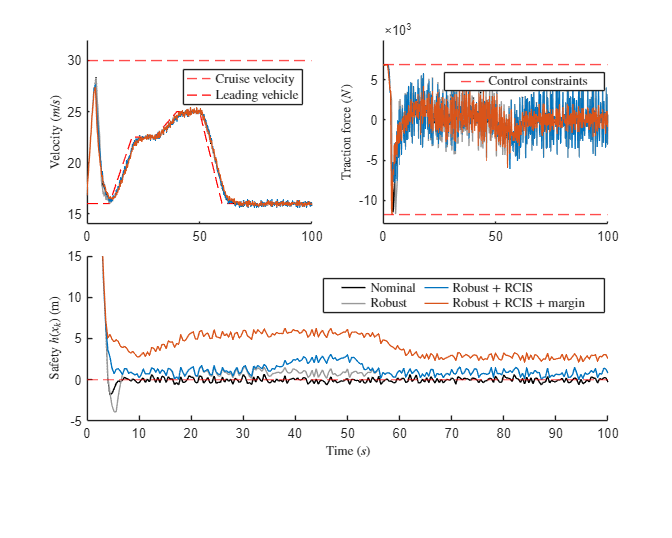


%% Figure: ACC2 – velocity, traction force, and safety function (4 controller cases)

rk = 30;
two_column_width = 7;      % Inches, roughly one IEEE column width
font_size        = 10;

% ---------- Controller case styles ----------
% Case 1: Nominal (no robustness, no RCIS, eps0 = 0)
% Case 2: Robust only
% Case 3: Robust + RCIS, eps0 = 0
% Case 4: Robust + RCIS + margin
caseColors = [ ...
    0.00 0.00 0.00;   % 1: black
    0.60 0.60 0.60;   % 2: light gray
    0.00 0.45 0.75;   % 3: blue
    0.85 0.33 0.10];  % 4: orange
caseWidth   = [0.7 0.5 1.0 1.0];
caseStyle   = {'-','-','-','-'};   % All solid lines
caseLabels  = {'Nominal','Robust','Robust + RCIS','Robust + RCIS + margin'};
nCases      = 4;

figure;
set(gcf,'Units','inches','Position',[1 1 two_column_width 0.8*two_column_width]);

%% ---------- (a) Velocity (top-left) ----------
ax_vel = subplot(2,2,1);
hold(ax_vel,'on');

% Cruise velocity & leading vehicle profile
h_cv = yline(ax_vel,rk,'--r','LineWidth',0.7);       % Cruise velocity
h_lv = plot(ax_vel,[0 10 20 30 40 50 60 100], ...
                     [16 16 22.5 22.5 25 25 16 16], ...
                     '--','Color','r','LineWidth',0.9);  % Leading vehicle speed

for i = 1:nCases
    t = simOut(i).X.time;
    v = simOut(i).X.signals.values(:,2);
    plot(ax_vel,t,v,'Color',caseColors(i,:), ...
                    'LineStyle',caseStyle{i}, ...
                    'LineWidth',caseWidth(i), ...
                    'HandleVisibility','off');
end

axis(ax_vel,[0 100 14 32]);
ylabel(ax_vel,'Velocity ($m/s$)','Interpreter','latex','FontSize',font_size);
set(ax_vel,'FontSize',font_size);
set(ax_vel,'LooseInset',get(ax_vel,'TightInset'));

leg_vel = legend(ax_vel,[h_cv h_lv],{'Cruise velocity','Leading vehicle'}, ...
                 'Interpreter','latex','FontSize',font_size,'Location','northeast');
set(findobj(leg_vel,'Type','line'),'LineWidth',0.5);
set(leg_vel,'ItemTokenSize',[18 6]);
pos = leg_vel.Position;
pos(2) = 0.805;   % Slightly higher
leg_vel.Position = pos;

%% ---------- (b) Traction force (top-right) ----------
ax_u = subplot(2,2,2);
hold(ax_u,'on');

h_u1 = yline(ax_u,max(Pu.V),'--r','LineWidth',0.7);
h_u2 = yline(ax_u,min(Pu.V),'--r','LineWidth',0.7);

for i = 1:nCases
    t = simOut(i).U.time;
    u = squeeze(simOut(i).U.signals.values);
    plot(ax_u,t,u,'Color',caseColors(i,:), ...
                  'LineStyle',caseStyle{i}, ...
                  'LineWidth',caseWidth(i), ...
                  'HandleVisibility','off');
end

axis(ax_u,[0 100 1.1*min(Pu.V) 1.45*max(Pu.V)]);
ylabel(ax_u,'Traction force ($N$)','Interpreter','latex','FontSize',font_size);
set(ax_u,'FontSize',font_size);
ax_u.YAxis.Exponent = 3;
set(ax_u,'LooseInset',get(ax_u,'TightInset'));

leg_u = legend(ax_u,[h_u1 h_u2],{'Control constraints'}, ...
               'Interpreter','latex','FontSize',font_size,'Location','northeast');
set(leg_u,'Units','normalized');
set(leg_u,'ItemTokenSize',[18 6]);
posu = leg_u.Position;
posu(1) = 0.66;   % Slightly to the center
posu(2) = 0.83;   % Slightly higher
posu(3) = 0.24;   % Control legend width
leg_u.Position = posu;

%% ---------- Precompute safety functions ----------
t_cases = cell(nCases,1);
h_cases = cell(nCases,1);
for i = 1:nCases
    t_cases{i} = simOut(i).X.time;
    h_cases{i} = -simOut(i).X.signals.values * Px.A(1,:)';
end

%% ---------- (c) Safety function (bottom, spanning two columns) ----------
ax_safe = subplot(2,2,[3 4]);
hold(ax_safe,'on');

h0 = yline(ax_safe,0,'--r','LineWidth',0.8);   % Reference line h(x_k)=0

h_plots = gobjects(nCases,1);
for i = 1:nCases
    t = t_cases{i};
    h = h_cases{i};
    idx   = 1:2:length(t);          % Subsample for readability
    tplot = t(idx);
    hplot = h(idx);
    h_plots(i) = plot(ax_safe,tplot,hplot,'Color',caseColors(i,:), ...
                                         'LineStyle',caseStyle{i}, ...
                                         'LineWidth',caseWidth(i));
end

axis(ax_safe,[0 100 -5 15]);
ylabel(ax_safe,'Safety $h(x_k)$ (m)','Interpreter','latex','FontSize',font_size);
xlabel(ax_safe,'Time ($s$)','Interpreter','latex','FontSize',font_size);
set(ax_safe,'FontSize',font_size);
set(ax_safe,'LooseInset',get(ax_safe,'TightInset'));

leg_safe = legend(ax_safe,h_plots,caseLabels, ...
    'Interpreter','latex','FontSize',font_size-1, ...
    'NumColumns',2,'Location','northwest');
set(leg_safe,'Units','normalized');
set(leg_safe,'ItemTokenSize',[18 6]);  
poss = leg_safe.Position;
poss(1) = 0.48;   % Move towards the center
poss(2) = 0.42;   % Slightly higher
poss(3) = 0.42;   % Control legend width
leg_safe.Position = poss;

%% ---------- Adjust vertical spacing between rows ----------
pos_vel  = get(ax_vel,'Position');
pos_u    = get(ax_u,'Position');
pos_safe = get(ax_safe,'Position');

gap       = 0.06;                 % Vertical gap between rows
bottom_h  = pos_safe(4)*0.9;      % Slightly shrink safety plot height
pos_safe(4) = bottom_h;
pos_safe(2) = min(pos_vel(2),pos_u(2)) - gap - bottom_h;

set(ax_vel,'Position',pos_vel);
set(ax_u,'Position',pos_u);
set(ax_safe,'Position',pos_safe);

%% ---------- Global font + export ----------
set(findall(gcf,'-property','FontSize'),'FontSize',font_size);
exportgraphics(gcf,'Figures/ACC2.eps','ContentType','vector');